# Part 2

inputImage = imread('cat.jpg');

h = size(inputImage, 1);
w = size(inputImage, 2);

% Change These Values for height and width
h_new = 400;
w_new = 600;

outputNN = uint8(zeros(h_new, w_new, 3));
outputBI = uint8(zeros(h_new, w_new, 3));

for y_new = 1:h_new
    for x_new = 1:w_new
        x = round(x_new * (w / w_new));
        y = round(y_new * (h / h_new));
        outputNN(y_new, x_new, :) = inputImage(y, x, :);
    end
end

for y_new = 1:h_new
    for x_new = 1:w_new
        x = x_new * (w / w_new);
        y = y_new * (h / h_new);
        
        x1 = floor(x);
        y1 = floor(y);
        x2 = ceil(x);
        y2 = ceil(y);
        
        dx = x - x1;
        dy = y - y1;
        
        pixel1 = inputImage(y1, x1, :);
        pixel2 = inputImage(y1, x2, :);
        pixel3 = inputImage(y2, x1, :);
        pixel4 = inputImage(y2, x2, :);
        
        interpolatedPixel = (1 - dx) * (1 - dy) * double(pixel1) + ...
                            dx * (1 - dy) * double(pixel2) + ...
                            (1 - dx) * dy * double(pixel3) + ...
                            dx * dy * double(pixel4);
        
        outputBI(y_new, x_new, :) = uint8(interpolatedPixel);
    end
end

imwrite(outputNN, "cat_near_2.jpg")
imwrite(outputBI, "cat_BI_2.jpg")


## Part 3

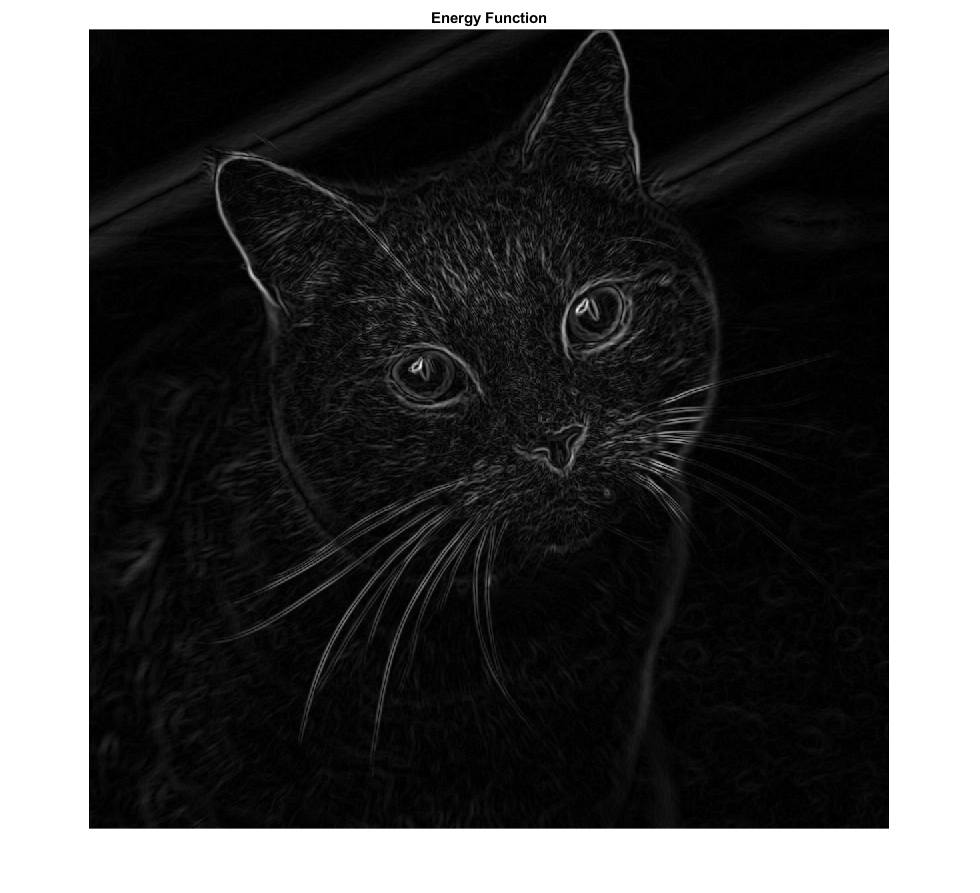

inputImage = imread('cat.jpg');

grayImage = rgb2gray(inputImage);

sigma = 1.5;

smoothedGrayImage = imgaussfilt(grayImage, sigma);

[Gx, Gy] = imgradientxy(smoothedGrayImage);

energy = sqrt(Gx.^2 + Gy.^2);

imshow(energy, []); title('Energy Function');

## Part 4

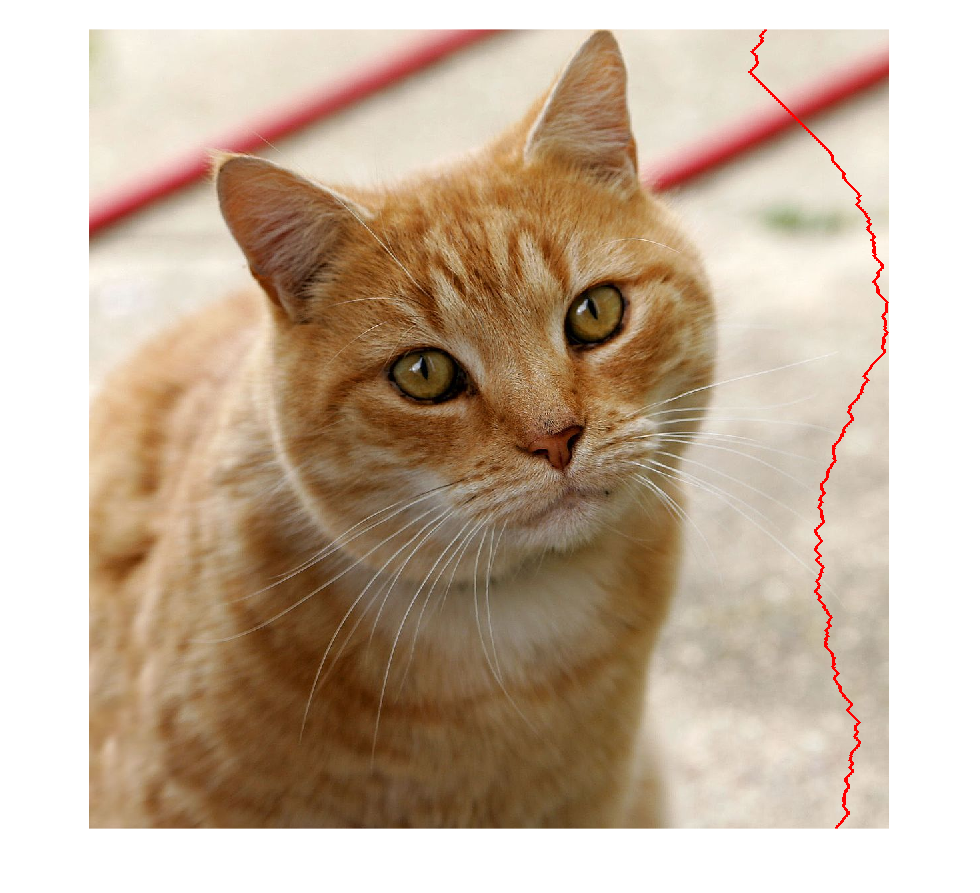


% Compute seam matrix
[rows, cols] = size(energy);
seamMatrix = zeros(rows, cols);
seamMatrix(1, :) = energy(1, :);
for i = 2:rows
    for j = 1:cols
        if j == 1
            seamMatrix(i, j) = energy(i, j) + min(seamMatrix(i-1, j), seamMatrix(i-1, j+1));
        elseif j == cols
            seamMatrix(i, j) = energy(i, j) + min(seamMatrix(i-1, j-1), seamMatrix(i-1, j));
        else
            seamMatrix(i, j) = energy(i, j) + min([seamMatrix(i-1, j-1), seamMatrix(i-1, j), seamMatrix(i-1, j+1)]);
        end
    end
end

% Find optimal seam
[~, startCol] = min(seamMatrix(rows, :));
seamPath = zeros(rows, 1);
seamPath(rows) = startCol;
for i = rows-1:-1:1
    if seamPath(i+1) == 1
        [~, minIndex] = min([seamMatrix(i, 1), seamMatrix(i, 2)]);
        seamPath(i) = minIndex;
    elseif seamPath(i+1) == cols
        [~, minIndex] = min([seamMatrix(i, cols-1), seamMatrix(i, cols)]);
        seamPath(i) = cols - 1;
    else
        [~, minIndex] = min([seamMatrix(i, seamPath(i+1)-1), seamMatrix(i, seamPath(i+1)), seamMatrix(i, seamPath(i+1)+1)]);
        seamPath(i) = seamPath(i+1) - 2 + minIndex;
    end
end

% Superimpose optimal seam on the color image with a thicker line
seamThickness = 5; % Adjust this value to change the thickness of the seam line
overlayedImage = inputImage;
for i = 1:rows
    startCol = seamPath(i);
    for offset = -floor(seamThickness/2):floor(seamThickness/2)
        col = startCol + offset;
        col = max(1, min(col, cols)); % Ensure column index is within bounds
        overlayedImage(i, col, 1) = 255;
        overlayedImage(i, col, 2) = 0;
        overlayedImage(i, col, 3) = 0;
    end
end

% Display the superimposed image
figure, imshow(overlayedImage);

## Part 5

inputImage = imread('cat.jpg');

grayImage = rgb2gray(inputImage);

sigma = 1.5;

smoothedGrayImage = imgaussfilt(grayImage, sigma);

[Gx, Gy] = imgradientxy(smoothedGrayImage);

energy = sqrt(Gx.^2 + Gy.^2);

% Compute seam matrix
[rows, cols] = size(energy);
seamMatrix = zeros(rows, cols);
seamMatrix(1, :) = energy(1, :);
for i = 2:rows
    for j = 1:cols
        if j == 1
            seamMatrix(i, j) = energy(i, j) + min(seamMatrix(i-1, j), seamMatrix(i-1, j+1));
        elseif j == cols
            seamMatrix(i, j) = energy(i, j) + min(seamMatrix(i-1, j-1), seamMatrix(i-1, j));
        else
            seamMatrix(i, j) = energy(i, j) + min([seamMatrix(i-1, j-1), seamMatrix(i-1, j), seamMatrix(i-1, j+1)]);
        end
    end
end

% Initialize video writer
outputVideo = VideoWriter('seamCat.mp4', 'MPEG-4');
open(outputVideo);
targetSize = [size(inputImage, 1), size(inputImage, 2)];
% Loop through the width reduction process
while cols > 1
    % Find optimal seam
    [~, startCol] = min(seamMatrix(rows, :));
    seamPath = zeros(rows, 1);
    seamPath(rows) = startCol;
    for i = rows-1:-1:1
        prevCol = seamPath(i+1); % Previous column index
        if prevCol == 1
            [~, minIndex] = min([seamMatrix(i, 1), seamMatrix(i, 2)]);
            seamPath(i) = minIndex;
        elseif prevCol == cols
            [~, minIndex] = min([seamMatrix(i, cols-1), seamMatrix(i, cols)]);
            seamPath(i) = cols - 1;
        else
            [~, minIndex] = min([seamMatrix(i, prevCol - 1), seamMatrix(i, prevCol), seamMatrix(i, prevCol + 1)]);
            seamPath(i) = prevCol - 2 + minIndex;
        end
    end
    
    % Superimpose optimal seam on the color image with a thicker line
    seamThickness = 5; % Adjust this value to change the thickness of the seam line
    overlayedImage = inputImage;
    for i = 1:rows
        startCol = seamPath(i);
        for offset = -floor(seamThickness/2):floor(seamThickness/2)
            col = startCol + offset;
            col = max(1, min(col, cols)); % Ensure column index is within bounds
            overlayedImage(i, col, 1) = 255;
            overlayedImage(i, col, 2) = 0;
            overlayedImage(i, col, 3) = 0;
        end
    end
    
    % Pad overlayedImage to match the target size
    padAmount = targetSize(2) - size(overlayedImage, 2);
    paddedOverlayedImage = padarray(overlayedImage, [0, padAmount], 0, 'post');
    
    % Write the frame to the video
    writeVideo(outputVideo, paddedOverlayedImage);
    
    % Remove the optimal seam column from the image and seamMatrix
    inputImage(:, startCol, :) = [];
    energy(:, startCol) = [];
    seamMatrix(:, startCol) = [];
    
    % Update the number of columns
    cols = cols - 1;
end


% Close the video writer
close(outputVideo);
